# Plotting LIDAR in Sensor Frame

Objective: This script is used to test *range2xy* function and show you how to use it to the transform LIDAR data to the **sensor frame.** This script takes the uses the LIDAR data, converts it to x-y coordinates using *range2xy* and plots the LIDAR data in the **sensor frame**. 

Cheat Sheet: In this script, you will use the following functions and CreateRobot properties:

- CreateRobot.angRangeLidar: Angular range of LIDAR sensor

- CreateRobot.rangeLidar: Linear range of LIDAR sensor

- CreateRobot.numPtsLidar: Number of points in LIDAR sensing range

- CreateRobot.angleArray: Array of LIDAR angles

- genLidar(CreateRobot): Generates a reading for the LIDAR sensor

For more information on these functions an properties, refer to the CreateRobot documentation 

help CreateRobot %in Command Window

  Creates definition of class, instances of which will include all
  properties and controls associated with a single CreateRobot robot

    Documentation for CreateRobot



Helper Functions used in this exercise:

- *plot_lidar_xy_sensor: *Plots the LIDAR readings in the sensor frame

Exercise:

In the Simulator, press the Read Sensors button to get the CreateRobot object that represents the current state of the robot. You will use the object (named **robotObj**) in this script. 

Complete the code below to:

- Initialize robot constraints based on the CreateRobot and sensor configuration. 

- Read the LIDAR sensor

- Use the *range2xy* function, transform the LIDAR data to x-y coordiantes in the sensor frame. 

**COMPLETE THE CODE BELOW**

%1. Initialize, get LIDAR Constants
angRangeLidar = robotObj.angRangeLidar; %Insert your code here
rangeLidar = robotObj.rangeLidar;%Insert your code here
numPtsLidar = robotObj.numPtsLidar;%Insert your code here
angleData= robotObj.angleArray; %Insert your code here
maxRange = 4; %Max range of the LIDAR


% 2. Read the LIDAR sensor
distLidar= genLidar(robotObj, map);%Insert your code here

%3. Transform data to sensor frame 
depthXY = range2xy(angleData, distLidar,maxRange); %Insert your code here

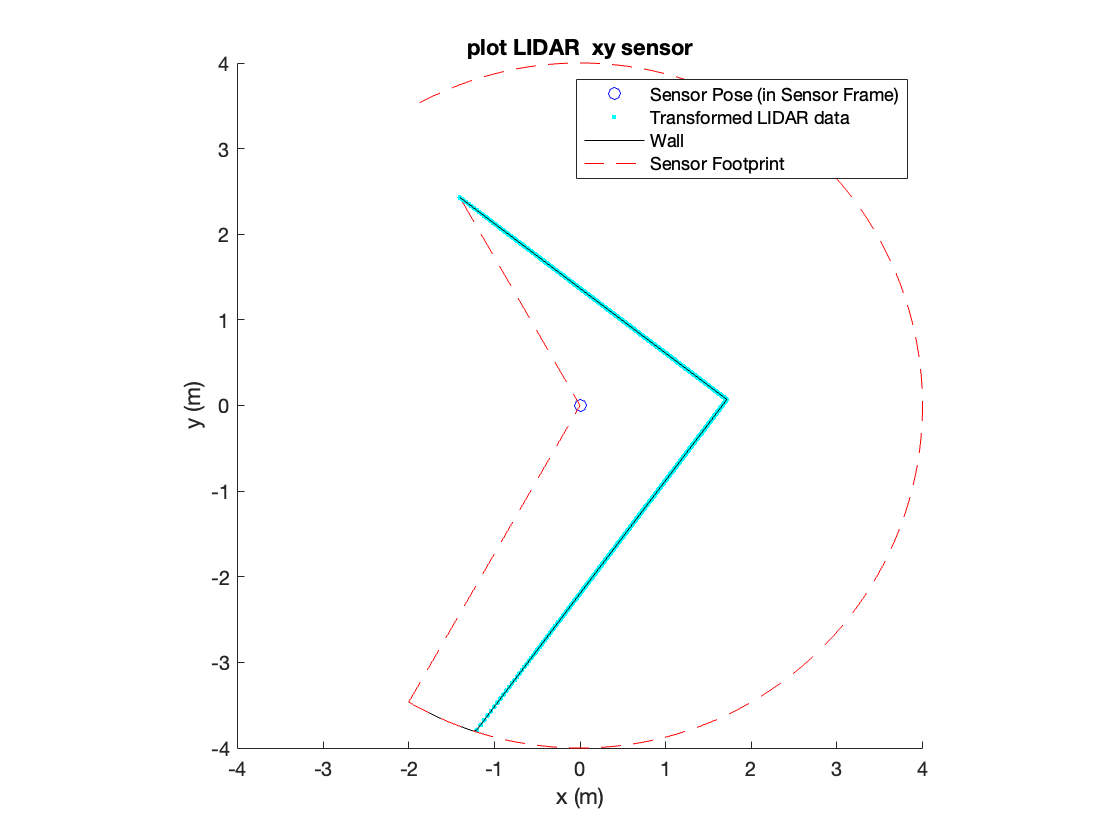

% --- Plot ----
plot_lidar_xy_sensor(maxRange, angleData,distLidar, depthXY, lidar)

Expected Results: Because you are plotting the LIDAR data in the **sensor frame**, you should see the sensor readings from the point of view of the sensor, where the sensor is located at 0,0 and pointing in the positive x direction. Readings that were at max range should not show up as they should now be "not a number" (NaN). This script plots  If your function is correct, your transformed LIDAR data (blue) should overlap with the plot of the wall (black line) that is within the LIDAR sensor footprint (red dashed line). 

Check your Comprehension:

Move the robot around the map facing different obstacles, are the x-y coordinates correct? Why is this plot of the walls sometimes rotated compared to the map displayed in the simulator? 